# Soft and Hard Iron Calibration

## Import data

clc; clear; close all;

rotation = load("trainingData/calib1_rotate.mat");
GT_rotation = squeeze(rotation.out.GT_rotation.signals.values);
GT_time = squeeze(rotation.out.GT_rotation.time);
time = squeeze(rotation.out.GT_time.signals.values);
Mraw = squeeze(rotation.out.Sensor_MAG.signals.values)';
M_time = squeeze(rotation.out.Sensor_MAG.time)';

Mx   = Mraw(:,2);
My   = Mraw(:,3);
scaleFactor = 1e5;

% Combine for 2D
XY_raw = [Mx, My];

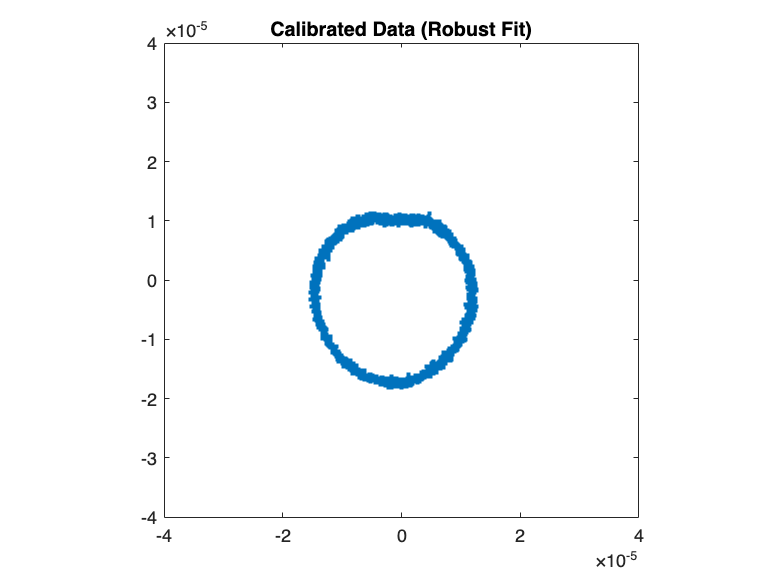

    0.8632

Percentage of inliers: 0.8632, Mean radius: 0.0000, Std deviation: 0.0000


function [calibratedData, offset, scaleMatrix] = calibrateMagnetometer2D_nonlinear(rawData)
    
    % Normalizing the raw data for Numerical Stability
    mu = mean(rawData);
    sigma = std(rawData);
    normData = (rawData - mu) ./ sigma;

    x = normData(:,1);
    y = normData(:,2);

    %% Step 1: Nonlinear ellipse fitting with robust loss
    % Parameters: [cx, cy, a, b, theta]
    x0 = [mean(x), mean(y), std(x), std(y), 0];  % initial guess

    % Residuals for robust optimization
    ellipseResiduals = @(p) (( ...
        ((x - p(1))*cos(p(5)) + (y - p(2))*sin(p(5))).^2 / p(3)^2 + ...
        ((x - p(1))*sin(p(5)) - (y - p(2))*cos(p(5))).^2 / p(4)^2 - 1 ...
    ));

    % Robust cost: log(1 + residual^2)
    robustCost = @(p) sum(log(1 + ellipseResiduals(p).^2));

    options = optimoptions('fminunc','Display','off','Algorithm','quasi-newton');
    p_fit = fminunc(robustCost, x0, options);

    %% Step 2: Outlier rejection
    res = ellipseResiduals(p_fit);
    threshold = 0.1;  % Can be tuned
    inliers = abs(res) < threshold;

    x_in = x(inliers);
    y_in = y(inliers);

    %% Step 3: Re-fit with inliers only (least-squares or robust again)
    ellipseResiduals_in = @(p) (( ...
        ((x_in - p(1))*cos(p(5)) + (y_in - p(2))*sin(p(5))).^2 / p(3)^2 + ...
        ((x_in - p(1))*sin(p(5)) - (y_in - p(2))*cos(p(5))).^2 / p(4)^2 - 1 ...
    ));

    p_fit = fminunc(@(p) sum(ellipseResiduals_in(p).^2), p_fit, options);

    %% Step 4: Calibration (translate, rotate, scale)
    cx = p_fit(1); cy = p_fit(2);
    a = p_fit(3); b = p_fit(4);
    theta = p_fit(5);

    offset_norm = [cx, cy];

    % Hard iron correction (translation)
    x_shift = x - cx;
    y_shift = y - cy;

    % Rotation matrix
    R = [cos(theta), -sin(theta); sin(theta), cos(theta)];
    rotated = R' * [x_shift'; y_shift'];

    % Soft iron correction (scaling)
    avg_scale = mean([1/a, 1/b]);
    scaleMatrix = diag([avg_scale, avg_scale]);
    calibrated_norm = scaleMatrix * rotated;

    % Denormalize: reverse scaling and offset
    calibratedData = (calibrated_norm' .* sigma) + mu;
    calibratedData = calibratedData - mean(calibratedData);

    %% Final offset and scale matrix in rawData space
    offset = mu + offset_norm .* sigma;
    scaleMatrix = scaleMatrix * R';

    %% Plotting
    figure;
    % subplot(1,2,1);
    % plot(rawData(:,1), rawData(:,2), '.');
    % title('Raw Magnetometer Data'); axis equal;

    % subplot(1,2,2);
    plot(calibratedData(:,1), calibratedData(:,2), '.');
    title('Calibrated Data (Robust Fit)'); 
    axis equal;
    xlim([-4e-5,4e-5])
    ylim([-4e-5,4e-5])

    %% Output diagnostics
    diagnostics.inlier_ratio = mean(inliers);
    disp(diagnostics.inlier_ratio)
    r = sqrt(sum(calibratedData.^2, 2));
    fprintf("Percentage of inliers: %.4f, Mean radius: %.4f, Std deviation: %.4f\n", diagnostics.inlier_ratio, mean(r), std(r));

end
[calMag, offset, scaleMatrix] = calibrateMagnetometer2D_nonlinear(XY_raw);

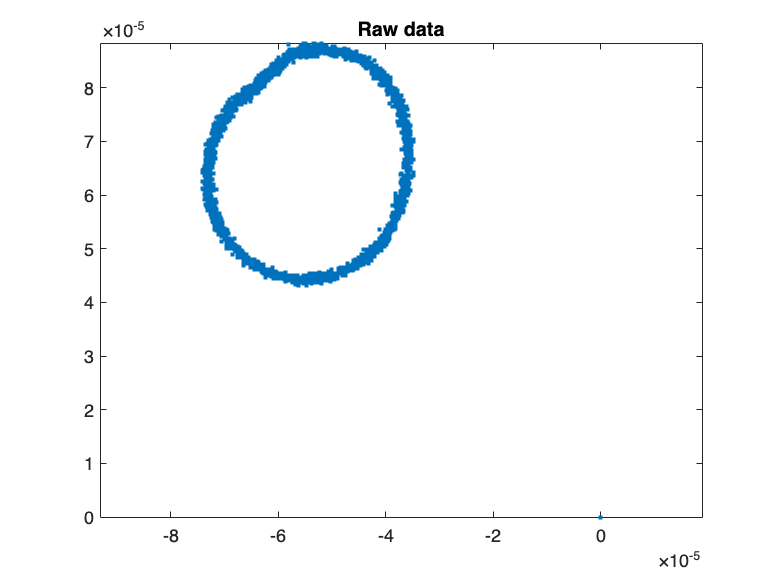


figure;
plot(XY_raw(:,1), XY_raw(:,2), '.');
title('Raw data'); 
axis equal;

yaw_gt = quat2eul(GT_rotation, 'ZXY');  % [yaw, pitch, roll]
yaw_gt = yaw_gt(:,1);                % Take yaw only (in radians)

% Unwrap to prevent jumps at ±π
yaw_gt = unwrap(yaw_gt);

% Do the same for your magnetometer yaw
yaw_mag = atan2(calMag(:,2), calMag(:,1))

yaw_mag =    -1.5119
   -1.5119
   -1.5119
   -1.5119
    1.0114
    1.0114
    0.9849
    0.9849
    0.9849
    0.9849


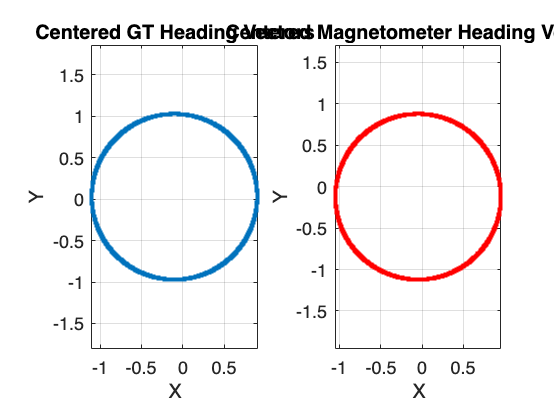

yaw_mag = unwrap(yaw_mag);

% Represent both as 2D heading vectors
v_gt = [cos(yaw_gt), sin(yaw_gt)];
v_mag = [cos(yaw_mag), sin(yaw_mag)];

% Center vectors (optional, helps numerical stability)
v_gt_centered = v_gt - mean(v_gt, 1);
v_mag_centered = v_mag - mean(v_mag, 1);

figure;
subplot(1,2,1);
plot(v_gt_centered(:,1), v_gt_centered(:,2), '.', 'DisplayName', 'GT');
axis equal; grid on;
xlabel('X'); ylabel('Y');
title('Centered GT Heading Vectors');

subplot(1,2,2);
plot(v_mag_centered(:,1), v_mag_centered(:,2), 'r.', 'DisplayName', 'Mag');
axis equal; grid on;
xlabel('X'); ylabel('Y');
title('Centered Magnetometer Heading Vectors');

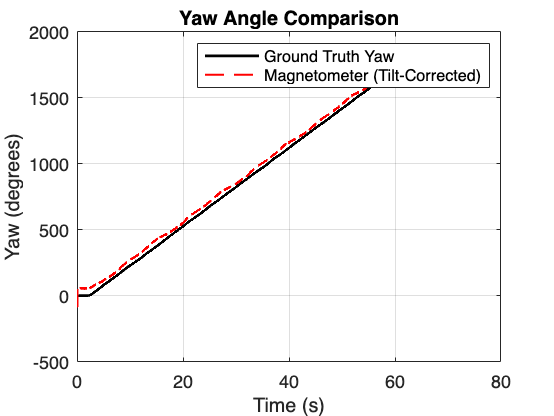


figure;
plot(time, rad2deg(abs(yaw_gt)), 'k', 'LineWidth', 1.5); hold on;
plot(M_time, rad2deg(yaw_mag), 'r--', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Yaw (degrees)');
legend('Ground Truth Yaw', 'Magnetometer (Tilt-Corrected)');
title('Yaw Angle Comparison');
grid on;


% CORRECT matrix multiplication:
% Compute 2x2 covariance matrix (not NxN)
C = v_mag_centered' * v_gt_centered;

% SVD on 2x2 matrix
[U, ~, V] = svd(C);

% Optimal rotation matrix (ensures proper rotation)
R_opt = V * U';

% Apply to all v_mag rows: each row is a 1x2 vector
v_mag_rot = (R_opt * v_mag_centered')';  % still Nx2

% Recover yaw from rotated vectors
yaw_mag_aligned = atan2(v_mag_rot(:,2), v_mag_rot(:,1));

% Compare
yaw_error = wrapToPi(yaw_mag_aligned - yaw_gt);
yaw_rmse = sqrt(mean(yaw_error.^2));
fprintf("RMSE after frame alignment: %.2f°\n", rad2deg(yaw_rmse));

RMSE after frame alignment: 11.66°
